# Param Search

Live script to identify best fit parameters for FHODB and CAPU NTD data and BNI1P single PRM data.

Quick start:

- Type in the variable name of the Experiment object in use in the Set Experiment Object section

- Generate plots by clicking Make plots

- Modify parameters by applying new parameters from a table or changing the rate constants directly. In either case, you must click the corresponding Run button to regenerate plots. Be sure to clear the output (View>Clear all Output) before generating new plots.

To change the plots being generated, modify the makeplots function.

 
makeplots(exp);

## Set Experiment Object

exp=Experiment1;
k_cap=exp.opts.k_cap;
k_del=exp.opts.k_del; 
r_cap=exp.opts.r_cap;
r_del=exp.opts.r_del; 
k_rel=exp.opts.k_rel; 

## Select Table to Apply

Data table with single row, containing Options and Formin class properties to apply

 
table=fit_3st;
exp.applytable(table)
disp(opts.optionstable)

                                                                                           
                     ______________________________________________________________________

    python_path      "/Users/katiebogue/MATLAB/GitHub/ForminKineticModel/main/python"      
    kpoly_type       "3st"                                                                 
    min_lenPRM       "4"                                                                   
    nInt             "1"                                                                   
    max_lenInt       "1"                                                                   
    min_nP           "1"                                                                   
    NTopt            "5"                                                                   
    CTopt 

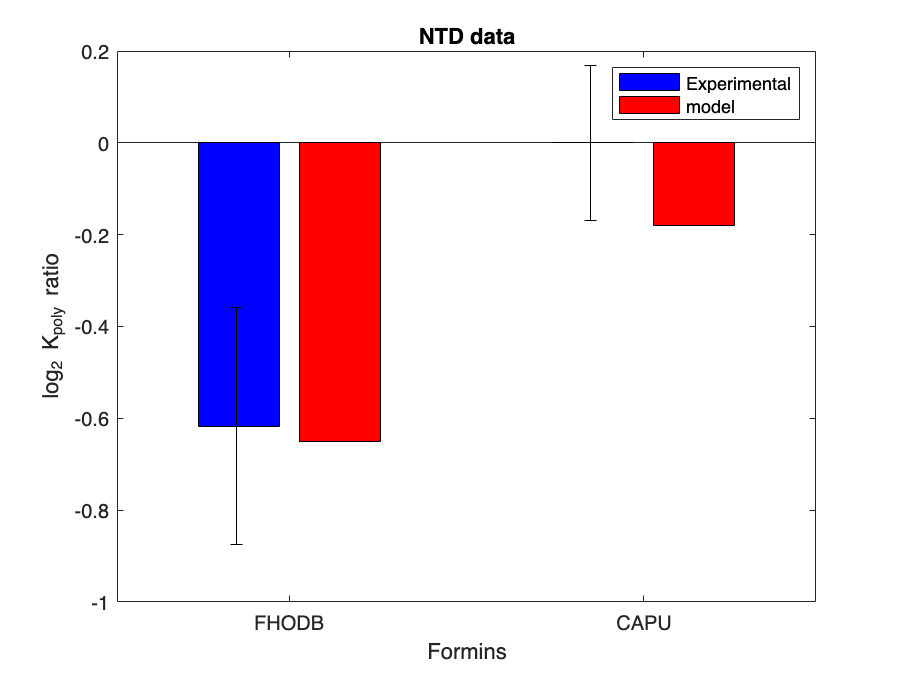

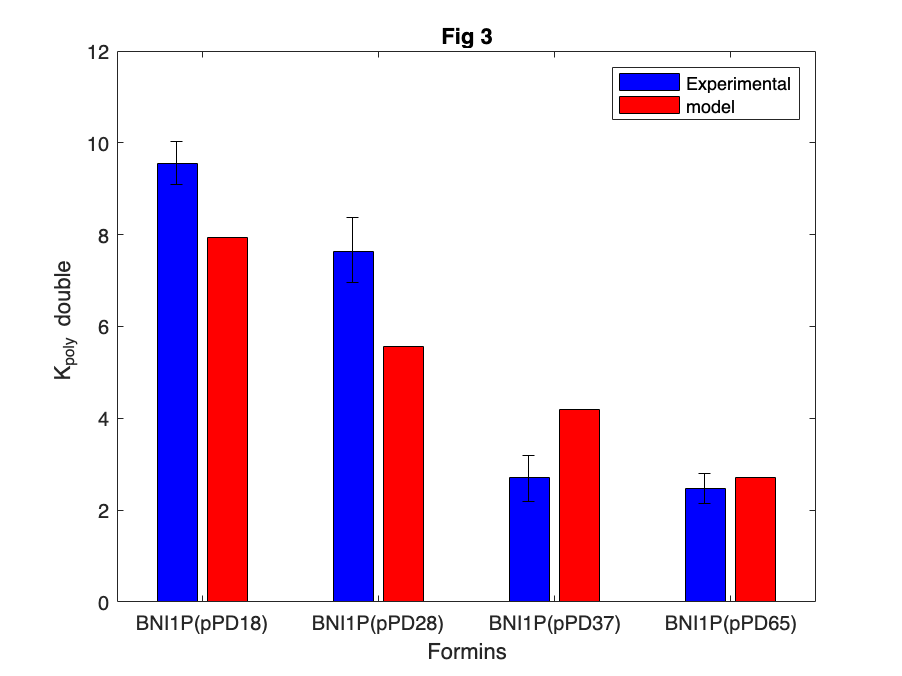

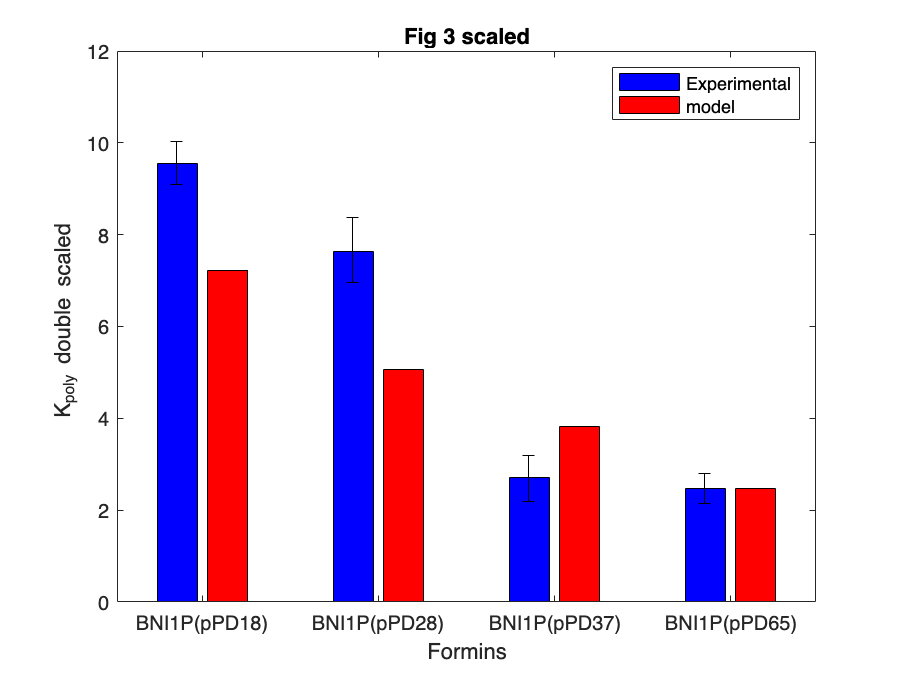

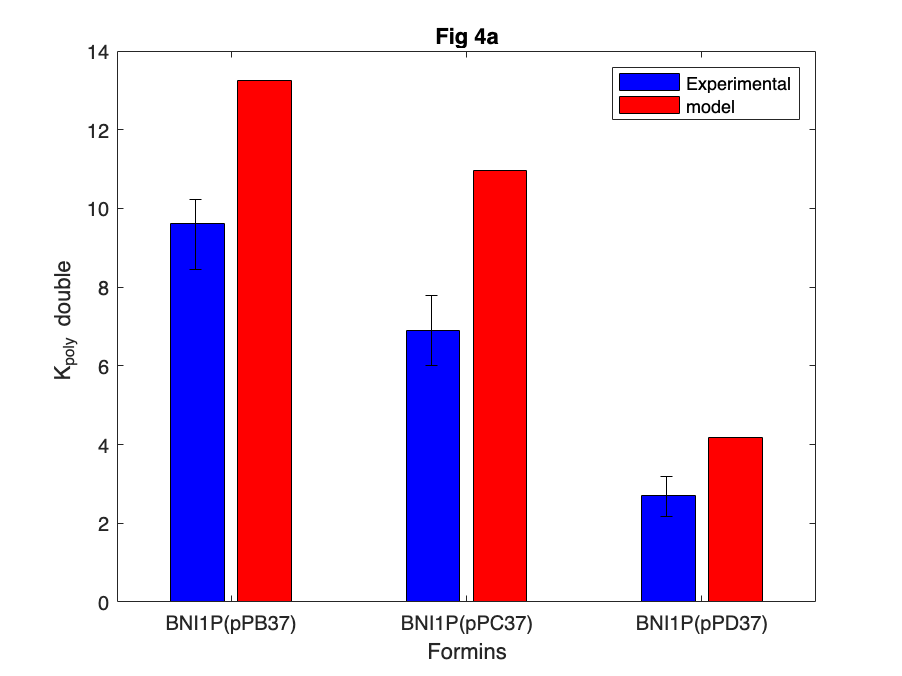

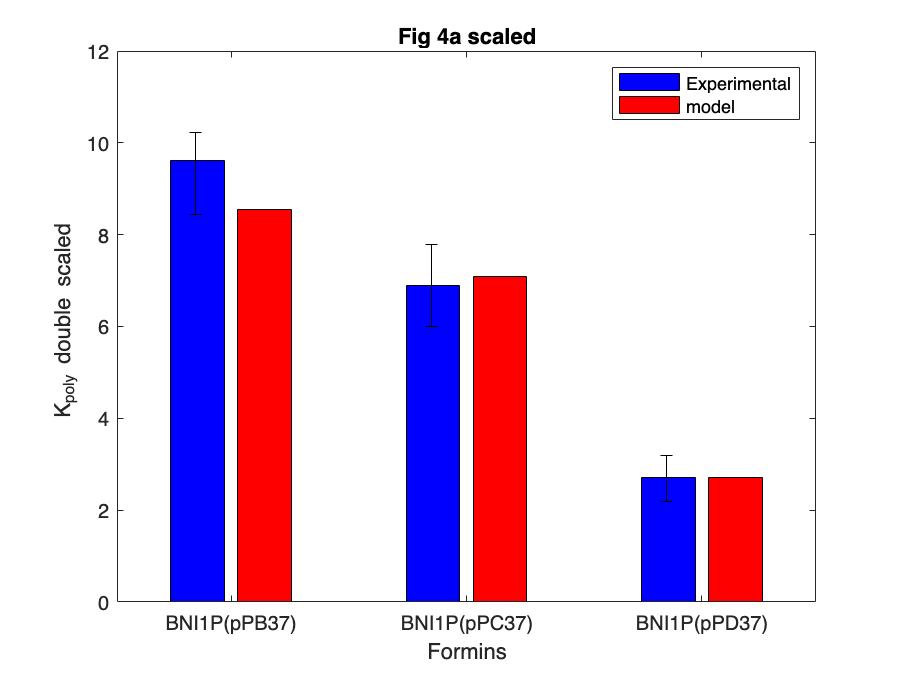

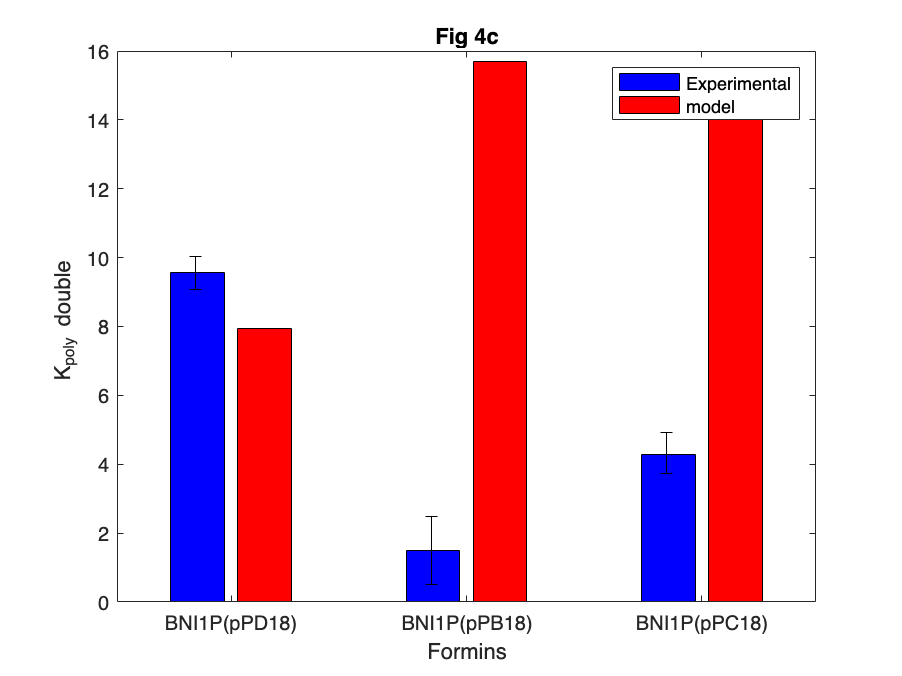

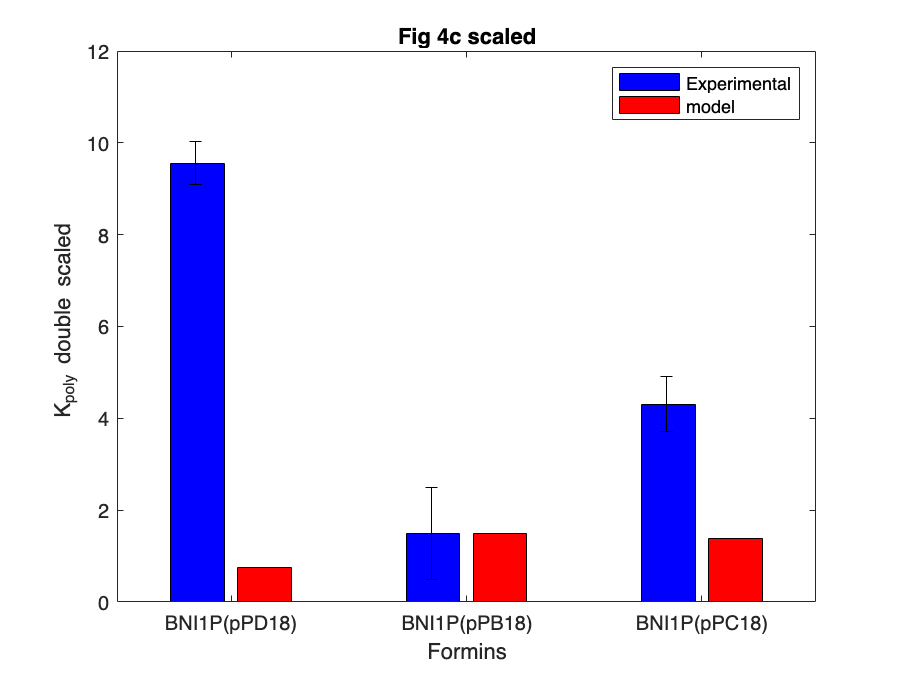

makeplots(exp);

## Modify Rate Constants

 
exp.opts.k_cap= 98.9;
exp.opts.k_del= 30.06;
exp.opts.r_cap= 48249;
exp.opts.r_del= 338119;
exp.opts.k_rel= 104;
disp(opts.optionstable)
makeplots(exp);

function makeplots(exp)
% MAKEPLOTS generates simulated vs. experimental data graphs for FHODB and CAPU NTD data and BNI1P single PRM data
    exp.expdatabar("log2",group="NTD data");
    
    exp.expdatabar(group="Fig 3");

    
    exp.expdatabar(group="Fig 4a");
    
    exp.expdatabar(group="Fig 4c");

    %exp.expdatabar(group="Fig 3 5");

end